
$$\begin{array}{l}
\text{ECSE}\text{ }307-\text{Winter}\text{ }2018\text{                                                                                                        }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{           }\text{ }\text{Professor}\text{ }\text{Aditya}\text{ }\text{Mahajan}\\
\text{                                                                                                                         }\text{ }\text{ }\text{ }\text{                       }\text{ }\text{TA}:\text{Mohammad}\text{ }\text{Afshari}\text{ }\text{and}\text{ }\text{Anas}\text{ }\text{El}\text{ }\text{Fathi}
\end{array}$$


# 
$$\text{Lab}\text{ }9$$


# 
$$\text{Lead}\text{ }\text{Compensation}\text{ }\mathrm{Desisgn}\text{ }\mathrm{for}\text{ }\mathrm{Qnet}\text{ }\mathrm{DC}\text{ }\mathrm{Motor}$$


%* Fill in your group number----------------------------------------------%
GroupeNum = 19;
%* Fill in your student Name and ID--------------------------------------*%
Students(1).Name = 'Yassine Douida';
Students(1).ID = '260741964';
Students(2).Name = 'Nayem Alam';
Students(2).ID = '260743549';
%-------------------------------------------------------------------------%

## **0. Objectives**

In this lab, the objective is to design a lead compensator to control the position of the rotor of Qnet DC Motor. First, we construct the state space model and the transfer function of the hardware we identified in Lab02. Then we design the lead compensator based on the frequency response and Bode plot of the continuous time system. This compensator is in continuous time and cannot be used to control the real discrete time hardware. To solve this problem, we transform the continuous time lead compensator to a discrete time transfer function. The last step is to implement this discrete time compensator and drive the motor. 

To verify that the hardware is working, run the following (You can ignore the warnings, but you shouldn't have any errors). Keep in mind that you have to have both of Lab09 and QnectDCMotor in the same directory.

Motor = QnetDCMotor();

## **1. State space representation of DC Motor**

Adding the position of the DC motor to the state space representation from Lab05 we have 


$$\theta^{˙} =\omega$$



$$ J \frac{d \omega}{dt} + b \omega = K_t i $$



$$ L \frac{d i}{dt} + R i = v - K_e \omega $$


where $\theta$ is the motor position in radian and $\omega$ is the motor speed (angular velocity). The parameters are defined as follow

Param.Kt = 0.034; % Torque proportionality constant (Kg m2 /s2/A) (N.m/A)
Param.Ke = 0.034; % Back electromotive proportionality constant (V/rad/s)
Param.L = 0.018; % Electric inductance (H)
Param.R = 8.4; % Terminal resistance (Ohm)
Param.J = 2e-05; % Rotor moment of inertia (kg.m2)
Param.b = 1e-06; % Rotor viscous friction constant (Kg.m2/s) (N.m.s)

From these differential equations we can represent the DC Motor state space model by the following 


$$ \frac{d}{dt}x(t) = \left[\matrix{ 0 & 1 & 0\cr 0 &-\frac{b}{J} & \frac{K_t}{J} \cr 0 &
-\frac{K_e}{L} & -\frac{R}{L} } \right] x(t) + \left[\matrix{ 0 \cr 0 \cr
\frac{1}{L} } \right] v(t) $$



$$y\left(t\right)=\left\lbrack \begin{array}{c}
1 & 0 & 0
\end{array}\right\rbrack x\left(t\right),$$


where $v(t)$ is the voltage and $y\left(t\right)$ is the output. The state vector contains the position $\theta \left(t\right)$, the angular velocity $\omega(t)$, and the current $i(t)$, and is given by


$$ x(t) = \left[\matrix{ \theta(t) \cr \omega(t) \cr i(t) } \right] $$


## *Question 1 (1 mark)*

Find the transfer function $G_{\text{ol}} \left(s\right)$ from the state space model.

% Place your code here
s = tf('s');
A = [0 1 0; 0 -Param.b/Param.J Param.Kt/Param.J; 0 -Param.Ke/Param.L -Param.R/Param.L];
B = [0;0;1/Param.L];
C = [1 0 0];
D =[0];

G= ss(A,B,C,D)


G =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0   -0.05    1700
   x3       0  -1.889  -466.7
 
  B = 
          u1
   x1      0
   x2      0
   x3  55.56
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Go1 = tf(G)


Go1 =
 
          9.444e04
  ------------------------
  s^3 + 466.7 s^2 + 3234 s
 
Continuous-time transfer function.



## 2. Continuous Time Lead Compensator Design

In this section, we want to design a lead compensator such that the following conditions are satisfied:

- The steady state error of the closed loop system to ramp input is less than 0.01.

- The phase margin of the compensated open loop system is at least ${45}^{\circ }$.

In order to see the closed loop system response to a ramp input, we define the following reference signal. Run the following code to see the defined reference input.

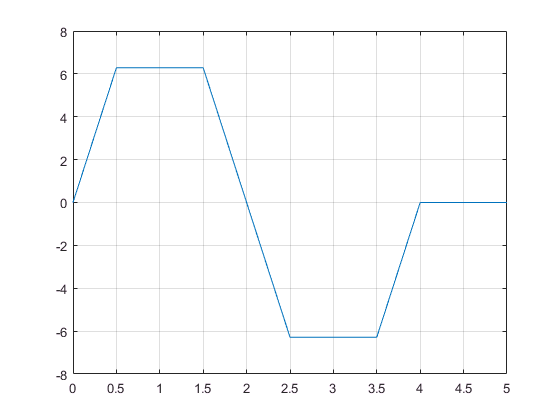

T = 5;        % Simulation duration
dt = 0.01;    % Simulation step time
time = 0:dt:T;% Time array

speedTarget = 2*2*pi; % target in radian

angleTarget = zeros(size(time));
angleTarget(time < 0.5) = speedTarget*time(time < 0.5);
angleTarget(time >= 0.5 & time < 1.5) = speedTarget/2;
angleTarget(time >= 1.5 & time < 2.5) = ...
    2*speedTarget - speedTarget*time(time >= 1.5 & time < 2.5);
angleTarget(time >= 2.5 & time < 3.5) = -speedTarget/2;
angleTarget(time >= 3.5 & time < 4.0) = ...
    -4*speedTarget + speedTarget*time(time >= 3.5 & time < 4.0);

figure(1);
plot(time, angleTarget)
grid on

As you know, a first order phase-lead compensator has the form given below:


$$C\left(s\right)=K\frac{1+\mathrm{Ts}}{1+\alpha \mathrm{Ts}}$$


where $K=K_c \alpha$. The open loop transfer function of the compensated system is 


$$G_{\text{ol}c} \left(s\right)=K\frac{1+\text{Ts}}{1+\alpha \text{Ts}}G_{\mathrm{ol}} \left(s\right)$$


In the follwoing question we repeat the steps if Lab08 to design a lead compensator in continuous time.

## *Question 2 (5 mark)*

1. Plot the Bode of $G_{\mathrm{ol}} \left(s\right)$.  

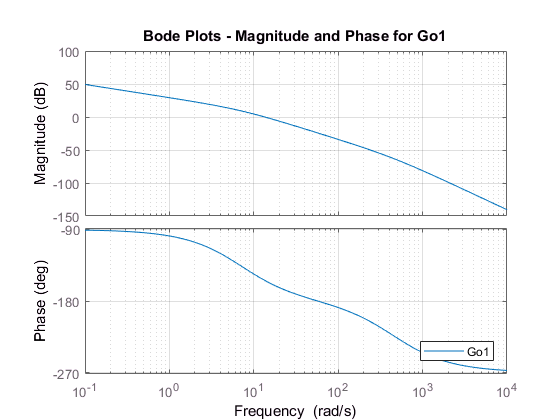

% Place your code here
bode(Go1) 
title(sprintf('Bode Plots - Magnitude and Phase for Go1'))
legend('Go1','Location','southeast')
grid on;

2. Design the lead compensator $K$such that the steady state error condition satisfies.

% Write your code here
Kv = dcgain(s*Go1)

Kv = 29.1996

K = (1/0.01)/Kv 

K = 3.4247

3. Produce the Bode plot of ${\mathrm{KG}}_{\mathrm{ol}} \left(s\right)$ and find the phase margin and gain margin of ${\mathrm{KG}}_{\mathrm{ol}} \left(s\right)$. 

% Write your code here
bode(K*Go1)
[Gm,Pm,Wgm,Wpm] = margin(K*Go1)

Gm = 4.6672

Pm = 11.8773

Wgm = 56.8722

Wpm = 26.0420

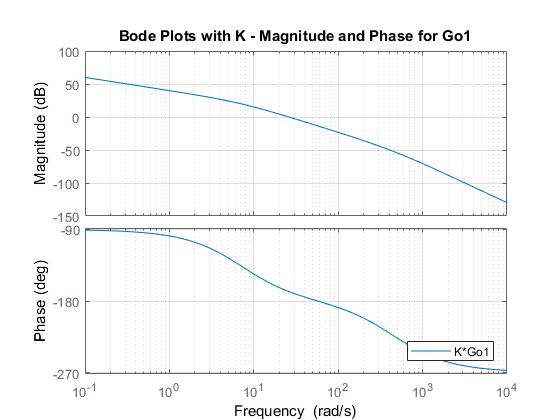

title(sprintf('Bode Plots with K - Magnitude and Phase for Go1'))
legend('K*Go1','Location','southeast')
grid on;

4. Desing the zero and pole of the compensator such that the phase margin condition satisfies. 

% Write your code here
Pm_offset = 45-Pm+10

Pm_offset = 43.1227

alpha = (1-sind(Pm_offset))/(1+sind(Pm_offset))

alpha = 0.1880

y= -20*log10(1/sqrt(alpha))

y = -7.2594

wm = 39.6; % found graphically 
T = 1/(sqrt(alpha)*wm)

T = 0.0582

Gc = K*((T*s+1)/(alpha*T*s+1)) % compensated TF


Gc =
 
  0.1995 s + 3.425
  ----------------
   0.01095 s + 1
 
Continuous-time transfer function.



pole(Gc)

ans = -91.3412

zero(Gc)

ans = -17.1682

5. Use margin to show the phase margin and gain margin of the final open loop compensated system on top of the bode plot.

% Write your code here
Golc = Gc*Go1


Golc =
 
             1.884e04 s + 3.234e05
  -------------------------------------------
  0.01095 s^4 + 6.11 s^3 + 502.1 s^2 + 3234 s
 
Continuous-time transfer function.



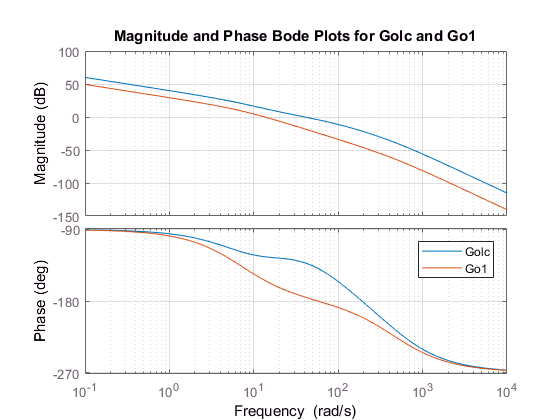

bode(Golc,Go1)
title(sprintf('Magnitude and Phase Bode Plots for Golc and Go1'))
legend('show')
grid on;

[Gm1,Pm1,Wgm1,Wpm1] = margin(Golc)

Gm1 = 11.6391

Pm1 = 48.1001

Wgm1 = 190.8405

Wpm1 = 40.0657

## *Question 3 (1.5 mark)*

Construct the closed loop transfer function of the compensated open loop system and plot the ramp response given the reference input in Section 1.

% Write your code here
Gc_loop = feedback(Gc*Go1,1)


Gc_loop =
 
                    1.884e04 s + 3.234e05
  ----------------------------------------------------------
  0.01095 s^4 + 6.11 s^3 + 502.1 s^2 + 2.207e04 s + 3.234e05
 
Continuous-time transfer function.



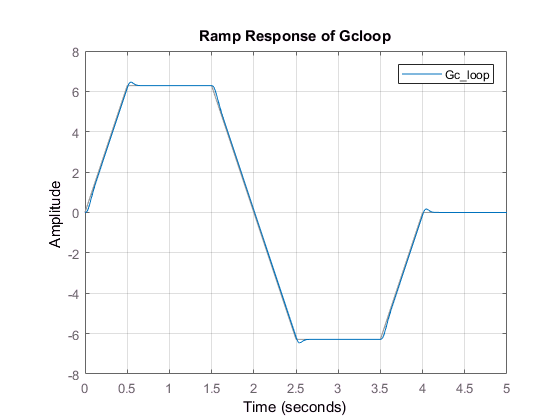

lsim(Gc_loop,angleTarget,time)
title(sprintf('Ramp Response of Gcloop'))
legend('show')
grid on;

## ***3. Hardware Implementation***

In this section, we see how to use the designed compensator for a real world system. In other words, we want to see how we can implement our lead compensator in discrete time. First we have to discretize the continuous time transfer function using the `c2d` function in MATLAB.

## ***Question 4 (1 mark)***

Find the lead compensator which you designed in the previous part in discrete time using the` c2d` function. Choose the sampling time equal to 0.01. Store the values of the zero, the pole and the gain separately. 

% Write your code here
Gcld = c2d(Gc,0.01)


Gcld =
 
  18.22 z - 16.17
  ---------------
    z - 0.4012
 
Sample time: 0.01 seconds
Discrete-time transfer function.



[z,p,k] = zpkdata(Gcld) 

z = cell
    [0.8874]


p = cell
    [0.4012]


k = 18.2207

Gcld_z = cell2mat(z) 

Gcld_z = 0.8874

Gcld_p = cell2mat(p)

Gcld_p = 0.4012

Now we want to run the DC motor with the designed discrete time lead compensator.

***Question 7 (1.5 mark)***

Complete the follwoing code to see the response of the system to the reference input given in the first section of this lab. Plot the output and the reference input as well as the voltage given to the motor.

% % Run the experiment
 err = 0;
 errOld = err;
 vOld = 0;
 Motor.reset();

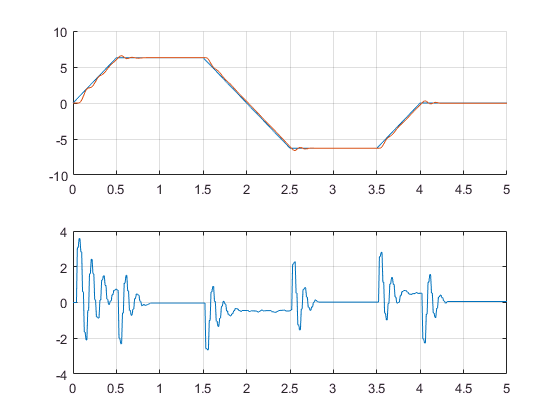

 for n = 1:length(time)
     t_ = time(n);
     
     a_ = Motor.angle(t_);
     err = angleTarget(n)-a_; %write the equation for error here;
     
     v_ = k*(err - (Gcld_z)*errOld) + (Gcld_p)*vOld;
     
    Motor.drive(v_, t_, dt);
     
     errOld = err;
 end
 Motor.off();

% % Get results of driving Qnet DC Motor
 t = Motor.time(0, t_);
 v = Motor.voltage(0, t_);
 i = Motor.current(0, t_);
 w = Motor.velocity(0, t_);
 a = Motor.angle(0, t_);
 
 % Plot results
 figure(4); clf;
 subplot(211)
 hold on
 %plot the reference input here
 plot(t,angleTarget)
 %plot the output here
 plot(t,a)
 grid on
 subplot(212)
 %plot the voltage here
 plot(t,v)
 grid on